终端约束角为: -16.7668°


绝对误差为: 0.0028135


相对误差为: 28.1346%


终端约束角为: -19.1066°


绝对误差为: 0.0023828


相对误差为: 19.8567%


终端约束角为: -21.4184°


绝对误差为: 0.0019931


相对误差为: 14.2366%


终端约束角为: -23.6989°


绝对误差为: 0.0016495


相对误差为: 10.3091%


终端约束角为: -25.9653°


绝对误差为: 0.0013356


相对误差为: 7.4201%


终端约束角为: -28.2659°


绝对误差为: 0.0010031


相对误差为: 5.0157%


终端约束角为: -30.8241°


绝对误差为: 0.00043465


相对误差为: 1.9757%


终端约束角为: -33.1663°


绝对误差为: 9.7592e-05


相对误差为: 0.40663%


终端约束角为: -35.5397°


绝对误差为: 0.00025132


相对误差为: 0.96663%


终端约束角为: -241.1252°


绝对误差为: 0.13343


相对误差为: 476.5202%


跳过 b = 0.028，因为角度差大于 120°


终端约束角为: -40.4143°


绝对误差为: 0.0010112


相对误差为: 3.3708%


终端约束角为: -42.9179°


绝对误差为: 0.0014203


相对误差为: 4.4384%


终端约束角为: -204.5502°


绝对误差为: 0.10189


相对误差为: 299.6809%


跳过 b = 0.034，因为角度差大于 120°


终端约束角为: -48.0619°


绝对误差为: 0.0022891


相对误差为: 6.3585%


终端约束角为: -50.7044°


绝对误差为: 0.002746


相对误差为: 7.2263%


终端约束角为: -53.3967°


绝对误差为: 0.0032169


相对误差为: 8.0421%


终端约束角为: -56.1381°


绝对误差为: 0.0036984


相对误差为: 8.8058%


终端约束角为: -58.9297°


绝对误差为: 0.0041887


相对误差为: 9.5199%


终端约束角为: -256.9686°


绝对误差为: 0.12649


相对误差为: 274.9705%


跳过 b = 0.046，因为角度差大于 120°


终端约束角为: -64.6737°


绝对误差为: 0.0051922


相对误差为: 10.8171%


终端约束角为: -67.631°


绝对误差为: 0.0057031


相对误差为: 11.4063%


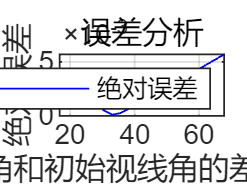

% 参数设置
qr_deg = linspace(20, 90, 10); % 视线角变化量范围（度）

qr = deg2rad(qr_deg); % 转换为弧度
qr_mid = qr_deg;
theta0_deg = 15; % 初始弹道倾角（度）
theta0 = deg2rad(theta0_deg);
N = 3; % 导航系数
v = 300; % 导弹速度（m/s）
r0 = 7500; % 初始距离（m）
q0 = 0; % 初始视线角（弧度）
% 预分配存储
b_theory = zeros(size(qr));
b_actual = zeros(size(qr));
absolute_error = zeros(size(qr));
relative_error = zeros(size(qr));
% 对每个qr计算理论b和实际b的误差
for i = 1:length(qr)
% 期望终端角度θf = q0 + qr（弧度）
theta_f = q0 + qr(i);
% 理论飞行时间
tf_theory = r0 / v;
% 理论b计算（公式13）
numerator = N*q0 - theta0 - (N-1)*theta_f;
b_theory(i) = numerator / tf_theory;
% 通过优化找到实际b使得θf_real = theta_f
options = optimset('TolX', 1e-6, 'Display', 'off');
b_actual(i) = fzero(@(b) compute_theta_error(b, N, v, r0, q0, theta0, theta_f), b_theory(i), options);
% 计算绝对误差
absolute_error(i) = b_actual(i) - b_theory(i);
% 计算相对误差
relative_error(i) = absolute_error(i) / abs(b_theory(i));
end
% 绘制结果
absolute_error_mid = absolute_error;
figure('Color', 'white');
yyaxis left;
plot(qr_deg, abs(relative_error), 'LineWidth', 2, 'DisplayName', '相对误差', 'Color', 'b');
ylabel('相对误差');
title('视线角变化量对误差的影响');
grid on;
yyaxis right;
plot(qr_deg, abs(absolute_error), 'LineWidth', 2, 'DisplayName', '绝对误差', 'Color', 'r');
ylabel('绝对误差');
% 添加图例
legend show;
xlabel('视线角变化量 q_r (°)');
function error = compute_theta_error(b, N, v, r0, q0, theta0, theta_f)
% 导弹运动方程
function dydt = dynamics(~, y)
r = y(1);
q = y(2);
theta = y(3);
eta = theta - q;
q_dot = -v * sin(eta) / r;
theta_dot = N * q_dot + b;
r_dot = -v * cos(eta);
dydt = [r_dot; q_dot; theta_dot];
end
% 事件函数：当r <= 1m时停止
function [value, isterminal, direction] = stop_event(~, y)
value = y(1) - 1;
isterminal = 1;
direction = -1;
end
% 初始条件
y0 = [r0; q0; theta0];
tspan = [0, 1000]; % 足够长的仿真时间
% 数值积分
options = odeset('Events', @stop_event, 'RelTol', 1e-6);
[~, y] = ode45(@dynamics, tspan, y0, options);
if isempty(y)
error = Inf;
else
theta_real = y(end, 3);
error = theta_real - theta_f; % 终端角度误差
end
end 

